sine = dsp.SineWave('Frequency',375,'SampleRate',8000,'SamplesPerFrame',1000)

sine =   dsp.SineWave with properties:

          Amplitude: 1
          Frequency: 375
        PhaseOffset: 0
      ComplexOutput: false
             Method: 'Trigonometric function'
         SampleRate: 8000
    SamplesPerFrame: 1000
     OutputDataType: 'double'


s = sine();
v = 0.8*randn(sine.SamplesPerFrame,1); % Random noise part.
ar = [1,1/2];          % Autoregression coefficients.
ARfilt = dsp.IIRFilter('Numerator',1,'Denominator',ar)

ARfilt =   dsp.IIRFilter with properties:

            Structure: 'Direct form II transposed'
            Numerator: 1
          Denominator: [1 0.5000]
    InitialConditions: 0

  Show all properties


v1 = ARfilt(v);
x = s + v1;
ma = [1, -0.8, 0.4, -0.2];
MAfilt = dsp.FIRFilter('Numerator',ma)

MAfilt =   dsp.FIRFilter with properties:

            Structure: 'Direct form'
      NumeratorSource: 'Property'
            Numerator: [1 -0.8000 0.4000 -0.2000]
    InitialConditions: 0

  Show all properties


v2 = MAfilt(v);
L = 7;
lms = dsp.LMSFilter(L,'Method','LMS')

lms =   dsp.LMSFilter with properties:

                   Method: 'LMS'
                   Length: 7
           StepSizeSource: 'Property'
                 StepSize: 0.1000
            LeakageFactor: 1
        InitialConditions: 0
           AdaptInputPort: false
    WeightsResetInputPort: false
            WeightsOutput: 'Last'

  Show all properties


nlms = dsp.LMSFilter(L,'Method','Normalized LMS')

nlms =   dsp.LMSFilter with properties:

                   Method: 'Normalized LMS'
                   Length: 7
           StepSizeSource: 'Property'
                 StepSize: 0.1000
            LeakageFactor: 1
        InitialConditions: 0
           AdaptInputPort: false
    WeightsResetInputPort: false
            WeightsOutput: 'Last'

  Show all properties


[mumaxlms,mumaxmselms] = maxstep(lms,x)

mumaxlms = 0.2111

mumaxmselms = 0.1350

[mumaxnlms,mumaxmsenlms] = maxstep(nlms,x)

mumaxnlms = 2

mumaxmsenlms = 2

lms.StepSize  = mumaxmselms/30 

lms =   dsp.LMSFilter with properties:

                   Method: 'LMS'
                   Length: 7
           StepSizeSource: 'Property'
                 StepSize: 0.0045
            LeakageFactor: 1
        InitialConditions: 0
           AdaptInputPort: false
    WeightsResetInputPort: false
            WeightsOutput: 'Last'

  Show all properties


nlms.StepSize = mumaxmsenlms/20 

nlms =   dsp.LMSFilter with properties:

                   Method: 'Normalized LMS'
                   Length: 7
           StepSizeSource: 'Property'
                 StepSize: 0.1000
            LeakageFactor: 1
        InitialConditions: 0
           AdaptInputPort: false
    WeightsResetInputPort: false
            WeightsOutput: 'Last'

  Show all properties


[~,elms,wlms] = lms(v2,x);
[~,enlms,wnlms] = nlms(v2,x);
reset(MAfilt);
bw = firwiener(L-1,v2,x); % Optimal FIR Wiener filter
MAfilt = dsp.FIRFilter('Numerator',bw)

MAfilt =   dsp.FIRFilter with properties:

            Structure: 'Direct form'
      NumeratorSource: 'Property'
            Numerator: [0.9851 0.2759 0.0683 0.0091 0.0947 0.0559 0.0224]
    InitialConditions: 0

  Show all properties


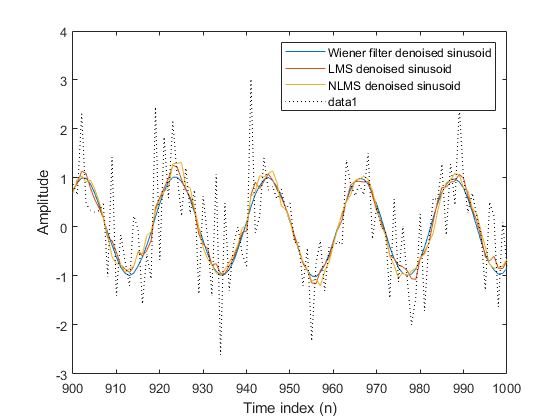

yw = MAfilt(v2); % Estimate of x using Wiener filter
ew = x - yw; % Estimate of actual sinusoid
n = (1:1000)';
plot(n(900:end),[ew(900:end), elms(900:end),enlms(900:end)])
legend('Wiener filter denoised sinusoid',...
    'LMS denoised sinusoid','NLMS denoised sinusoid')
xlabel('Time index (n)')
ylabel('Amplitude')
hold on
plot(n(900:end),x(900:end),'k:')
xlabel('Time index (n)')
ylabel('Amplitude')
hold off

[bw.' wlms wnlms]

ans =     0.9851    0.8566    0.9266
    0.2759    0.1025    0.1856
    0.0683   -0.0357   -0.0853
    0.0091   -0.0431   -0.1586
    0.0947    0.0390   -0.1114
    0.0559    0.0071   -0.1147
    0.0224   -0.0079   -0.1076


[ylms,elms,wlms] = lms(v2,x);
[ynlms,enlms,wnlms] = nlms(v2,x);
reset(ARfilt)
reset(sine);
release(sine);
n = (1:5000)';
sine.SamplesPerFrame = 5000

sine =   dsp.SineWave with properties:

          Amplitude: 1
          Frequency: 375
        PhaseOffset: 0
      ComplexOutput: false
             Method: 'Trigonometric function'
         SampleRate: 8000
    SamplesPerFrame: 5000
     OutputDataType: 'double'


s = sine();
nr = 25;
v = 0.8*randn(sine.SamplesPerFrame,nr);
ARfilt = dsp.IIRFilter('Numerator',1,'Denominator',ar)

ARfilt =   dsp.IIRFilter with properties:

            Structure: 'Direct form II transposed'
            Numerator: 1
          Denominator: [1 0.5000]
    InitialConditions: 0

  Show all properties


v1 = ARfilt(v);
x = repmat(s,1,nr) + v1;
reset(MAfilt);
MAfilt = dsp.FIRFilter('Numerator',ma)

MAfilt =   dsp.FIRFilter with properties:

            Structure: 'Direct form'
      NumeratorSource: 'Property'
            Numerator: [1 -0.8000 0.4000 -0.2000]
    InitialConditions: 0

  Show all properties


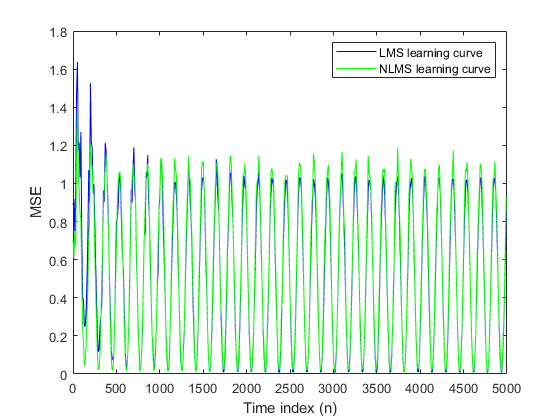

v2 = MAfilt(v);
reset(lms);
reset(nlms);
M = 10; % Decimation factor
mselms = msesim(lms,v2,x,M);
msenlms = msesim(nlms,v2,x,M);
plot(1:M:n(end),mselms,'b',1:M:n(end),msenlms,'g')
legend('LMS learning curve','NLMS learning curve')
xlabel('Time index (n)')
ylabel('MSE')

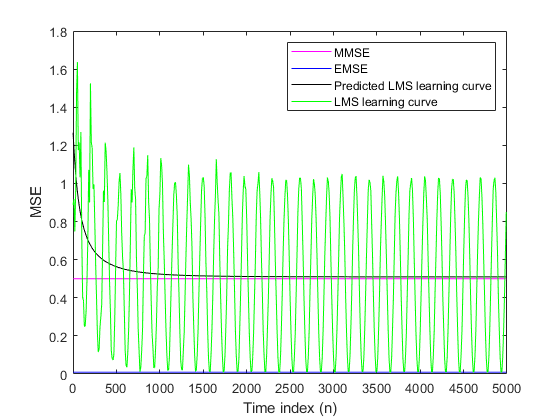

reset(lms);
[mmselms,emselms,meanwlms,pmselms] = msepred(lms,v2,x,M);
x = 1:M:n(end);
y1 = mmselms*ones(500,1);
y2 = emselms*ones(500,1);
y3 = pmselms;
y4 = mselms;
plot(x,y1,'m',x,y2,'b',x,y3,'k',x,y4,'g')
legend('MMSE','EMSE','Predicted LMS learning curve',...
    'LMS learning curve')
xlabel('Time index (n)')
ylabel('MSE')